# Titanic - Machine Learning from Disaster

Copyright @ *Nabajeet Barman (nabajeetbarman4@gmail.com)*

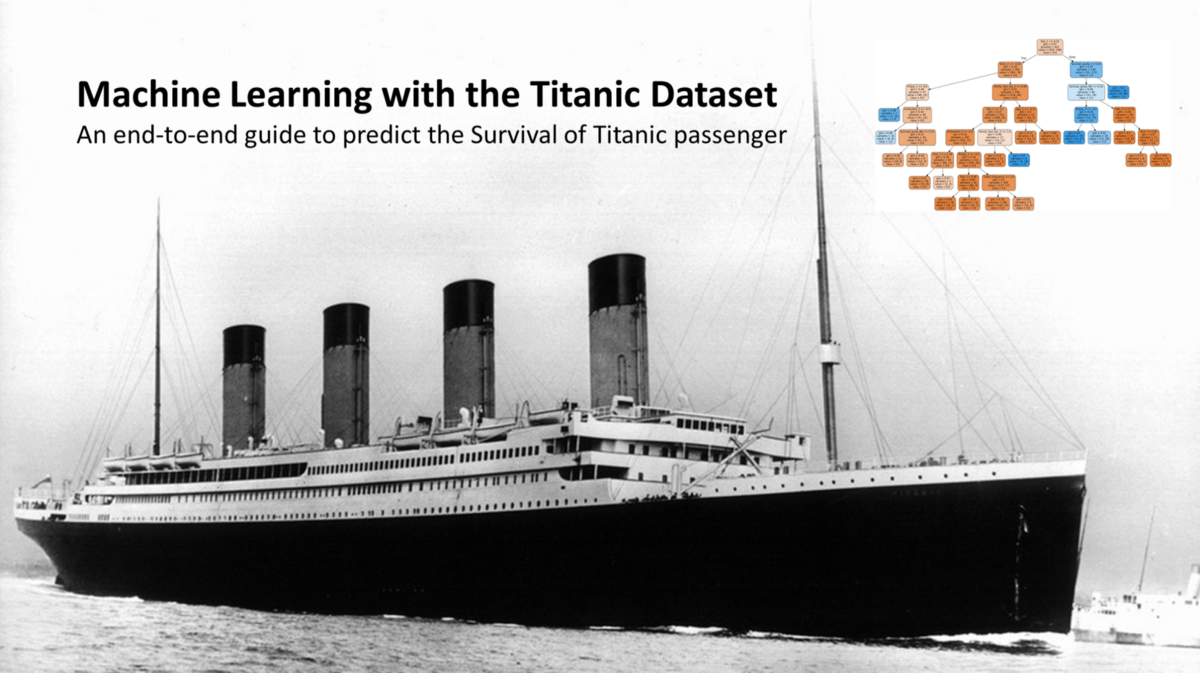

                                                                [Image Courtesy](https://www.google.com/url?sa=i&url=https%3A%2F%2Ftowardsdatascience.com%2Fmachine-learning-with-the-titanic-dataset-7f6909e58280&psig=AOvVaw2jxFkJxaAxJCgXVPJZCJOt&ust=1614108599149000&source=images&cd=vfe&ved=0CAQQjRxqFwoTCKiqlaCd_u4CFQAAAAAdAAAAABAD) 

#####################################################################################

Titanic dataset, originally posted on Kaggle is the first dataset that is used by any Data Scientist. Over the years, it has been the de-facto dataset for DS over the past several years due to its simplicity.

You can read more about the dataset [here](https://www.kaggle.com/c/titanic/data)

## Importing the Dataset

Download the dataset file, titanic.csv file from [Box](https://kingston.box.com/s/14vyphrk4yhvy4jc6z0653xt3166fjw7)

### Setup the Import Options and import the data

clear;
close all;
clc;

opts = delimitedTextImportOptions("NumVariables", 12);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["PassengerId", "Survived", "Pclass", "Name", "Sex", "Age", "SibSp", "Parch", "Ticket", "Fare", "Cabin", "Embarked"];
opts.VariableTypes = ["double", "categorical", "categorical", "string", "categorical", "double", "categorical", "double", "string", "double", "string", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Name", "Cabin"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Name", "Sex", "Cabin", "Embarked"], "EmptyFieldRule", "auto");

% Import the data
titanic = readtable("C:\Users\Nabajeet Barman\Dropbox\MA6600\Workshop02-25Feb\titanic.csv", opts)

titanic = 891×12 table
    PassengerId    Survived    Pclass                            Name                              Sex      Age    SibSp    Parch          Ticket           Fare     Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ______    ___    _____    _____    __________________    ______    ______    ________

         1            0          3       "Braund, Mr. Owen Harris"                                male       22      1        0      "A/5 21171"             7.25    ""           S    
         2      

### Clear temporary variables

% to use them later, i have commented this out
% clear opts

To check the datatype of the table column!!

class(titanic.Pclass)

ans = 'categorical'

## Understanding the Titanic Dataset

The Titanic data set consists of the following data columns:

- **PassengerId**: Id of every passenger.

- **Survived**: This feature have value 0 and 1. **0** for **not survived** and **1** for **survived**.

- **Pclass**: There are 3 classes: Class 1, Class 2 and Class 3.

- **Name**: Name of passenger.

- **Sex**: Gender of passenger.

- **Age**: Age of passenger.

- **SibSp**: Indication that passenger have siblings and spouse.

- **Parch**: Whether a passenger is alone or have family.

- **Ticket**: Ticket number of passenger.

- **Fare**: Indicating the fare.

- **Cabin**: The cabin of passenger.

- **Embarked**: The embarked category.

            Notes:

            *pclass*: A proxy for socio-economic status (SES)

- 1st = Upper

- 2nd = Middle

- 3rd = Lower

            *sibsp*: The dataset defines family relations in this way…

- Sibling = brother, sister, stepbrother, stepsister

- Spouse = husband, wife (mistresses and fiancés were ignored)

            *parch*: The dataset defines family relations in this way…

- Parent = mother, father

- Child = daughter, son, stepdaughter, stepson

- Some children travelled only with a nanny, therefore parch=0 for them.

**The ‘Survived’ column is our binary *****target***** variable which we need to predict; where 0- Not Survived, 1- Survived.**

## Save the excel file for sharing or off-Matlab use

writetable(titanic,'titanic_modified.csv')
% save the file after done with the basic pre-processing steps, so that you
% do not need to run that part of the code everytime.

Previewing the file at any stage

titanic(1:5,:)

ans = 5×12 table
    PassengerId    Survived    Pclass                            Name                              Sex      Age    SibSp    Parch          Ticket           Fare     Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ______    ___    _____    _____    __________________    ______    ______    ________

         1            0          3       "Braund, Mr. Owen Harris"                                male      22       1        0      "A/5 21171"             7.25    ""           S    
         2            

or alternatively

disp(titanic)

    PassengerId    Survived    Pclass                                            Name                                             Sex      Age     SibSp    Parch           Ticket            Fare           Cabin           Embarked  
    ___________    ________    ______    ____________________________________________________________________________________    ______    ____    _____    _____    ____________________    ______    _________________    ___________

          1           0          3       "Braund, Mr. Owen Harris"                                                             

or alternatively, like Python Pandas

head(titanic)

ans = 8×12 table
    PassengerId    Survived    Pclass                            Name                              Sex      Age    SibSp    Parch          Ticket           Fare     Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ______    ___    _____    _____    __________________    ______    ______    ________

         1            0          3       "Braund, Mr. Owen Harris"                                male       22      1        0      "A/5 21171"             7.25    ""           S    
         2            

Get the dataset dimension

size(titanic) % rows columns   

ans =    891    12


## Preliminary Data Analysis and Preprocessing

In the previous step, we have used the MATLAB's import function to import the text file, add meaningful column names, 

and started this live script

### Printing Summary Stats

summary(titanic) % remember the lecture slides - summary stats might be misleading!!!


Variables:

    PassengerId: 891×1 double

        Values:

            Min              1     
            Median         446     
            Max            891     

    Survived: 891×1 categorical

        Values:

            0       549    
            1       342    

    Pclass: 891×1 categorical

        Values:

            1      216   
            2      184   
            3      491   

    Name: 891×1 string

    Sex: 891×1 categorical

        Values:

            female     314 
            male       577 

    Age: 891×1 double

        Values:

            Min             0.42  
            Median          28    
            Max             80    
            NumMissing      177   

    SibSp: 891×1 categorical

        Values:

            0      608  
            1      209  
            2       28  
            3       16  
            4       18 

Getting summary stats values for analysis later

summary_vals = summary(titanic);
sprintf("The minimum age values is %s",summary_vals.Age.Min)

ans = "The minimum age values is 4.200000e-01"

Grouping variables and calculating stats

varfun(@mean,titanic,'InputVariables','Age',...
       'GroupingVariables','Sex')

ans = 2×3 table
     Sex      GroupCount    mean_Age
    ______    __________    ________

    female       314          NaN   
    male         577          NaN   


### [Handling Missing Data](https://www.mathworks.com/help/matlab/matlab_prog/clean-messy-and-missing-data-in-tables.html)

Standard missing data is defined as:

- NaN                   - for double and single floating-point arrays

- NaN                   - for duration and calendarDuration arrays

- NaT                   - for datetime arrays

- <missing>             - for string arrays

- <undefined>           - for categorical arrays

- blank character [' '] - for character arrays

- empty character {''}  - for cell arrays of character vectors

`ismissing` handles leading and trailing white space differently for indicators that are cell arrays of character vectors, character arrays, or categorical arrays.

- For cell arrays of character vectors, `ismissing` does not ignore indicator white space. All character vectors must match exactly.

- For character arrays in table variables, `ismissing` ignores trailing white space in the indicator.

- For categorical arrays, `ismissing` ignores leading and trailing white space in the indicator.

#### Using "Task" control functionality

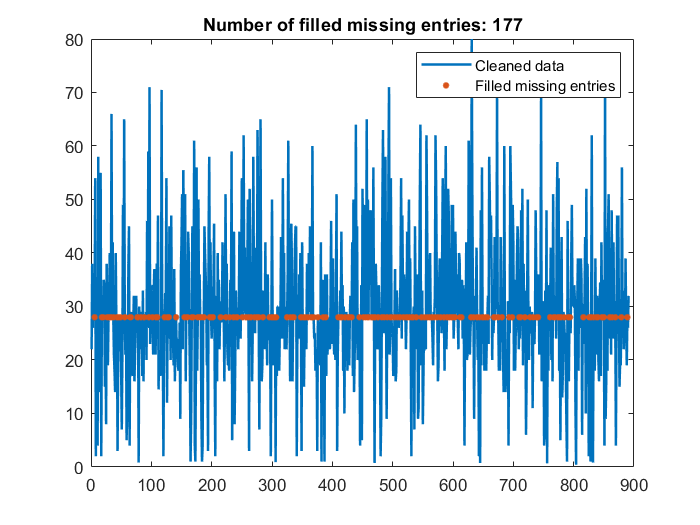

% Fill missing data
[cleanedData,missingIndices] = fillmissing(titanic.Age,'constant',28);

% Visualize results
clf
plot(cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')
hold on

% Plot filled missing entries
plot(find(missingIndices),cleanedData(missingIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices))])

hold off
legend

clear missingIndices

titanic % the Age column still has missing values - remember to reassign the values to the table columns (in-place equivalent in Python Pandas)

titanic = 891×12 table
    PassengerId    Survived    Pclass                            Name                              Sex      Age    SibSp    Parch          Ticket           Fare     Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ______    ___    _____    _____    __________________    ______    ______    ________

         1            0          3       "Braund, Mr. Owen Harris"                                male       22      1        0      "A/5 21171"             7.25    ""           S    
         2      

#### Doing programmatically by writing code

id = {"" '' '.' '<undefined>' 'NA' NaN -99 Inf}; % Define which type of data you will consider as "missing". Using this, you can actually
TF = ismissing(titanic,id);
rowsWithMissing = titanic(any(TF,2),:); % any(A,2) Test the rows of A for nonzero elements by specifying dim = 2
%disp(rowsWithMissing)
size(rowsWithMissing)

ans =    708    12


One of the **easiest** (but not always the correct) approach is to remove all observations with missing data

% Remove Rows with Missing Values
titanic_rows = rmmissing(titanic(any(TF,2),:));
disp(titanic_rows)

    PassengerId    Survived    Pclass                                    Name                                      Sex      Age     SibSp    Parch           Ticket            Fare     Cabin    Embarked
    ___________    ________    ______    _____________________________________________________________________    ______    ____    _____    _____    ____________________    ______    _____    ________

          1           0          3       "Braund, Mr. Owen Harris"                                                male        22      1        0      "A/5 21171"               7.25     ""

This is NOT a good approach as it might result in loss of lots of important data (we are left with only 362 observations)

size(titanic_rows)

ans =    529    12


#### Removing Columns

sum(ismissing(titanic,{"" '' '.' '<undefined>' 'NA' NaN -99}))

ans =      0     0     0     0     0   177     0     0     0     0   687     2


We see from above that, quite a lot - 687 (approx 70%) of values of Cabin are missing. Similarly, 177 data entries for column Age is missing. Dealing with missing values is tricky, as discussed earlier. We simply cannot remove 687 rows for Cabin or 177 rows for Ages. But we can (and we will) drop the Cabin column (as most of its values are missing an it does not add any value to the dataset). Other than Age and Cabin, Embarked column has 2 missing values.

titanic = removevars(titanic,{'Cabin'})

titanic = 891×11 table
    PassengerId    Survived    Pclass                            Name                              Sex      Age    SibSp    Parch          Ticket           Fare     Embarked
    ___________    ________    ______    _____________________________________________________    ______    ___    _____    _____    __________________    ______    ________

         1            0          3       "Braund, Mr. Owen Harris"                                male       22      1        0      "A/5 21171"             7.25       S    
         2            1          1       "Cumings, Mrs. John Bradley (Florence B

size(titanic)

ans =    891    11


% Just for Information
% T.Properties.VariableNames{end} = 'Final' ----> rename the last column
% T.EleventhColumn = rand(8,1); - to add a new column towards the end

Replacing missing Age values using the Median

titanic.Age = fillmissing(titanic.Age,'constant',summary_vals.Age.Median); % size(titanic,2) is the size 
                                                           % of the number of rows
%disp(titanic)

Check for missing values in another column - Embarked column (categorical variable)

First lets check the number of occurrence of values of Embarked column

tabulate(titanic.Embarked) % tabulate(x) displays a frequency table of the data in the vector x.  

  Value    Count   Percent
      C      168     18.90%
      Q       77      8.66%
      S      644     72.44%


% For each unique value in x, the tabulate function shows the number of instances and percentage of that value in x.

We see that Embarked class 'S' occurs the highest number of times - hence we replace the missing values with Class 'S'

titanic.Embarked = fillmissing(titanic.Embarked,'constant','S') 

titanic = 891×11 table
    PassengerId    Survived    Pclass                            Name                              Sex      Age    SibSp    Parch          Ticket           Fare     Embarked
    ___________    ________    ______    _____________________________________________________    ______    ___    _____    _____    __________________    ______    ________

         1            0          3       "Braund, Mr. Owen Harris"                                male      22       1        0      "A/5 21171"             7.25       S    
         2            1          1       "Cumings, Mrs. John Bradley (Florence B

%titanic = fillmissing(titanic,'constant','S','DataVariables',{'Embarked'})

Check if the Embarked column is not without any missing value

 tabulate(ismissing(titanic.Embarked))

  Value    Count   Percent
      0      891    100.00%


A final check to see if all missing values are now handled

%tabulate(ismissing(titanic))
TF = ismissing(titanic);
rowsWithMissing = titanic(any(TF,2),:)


rowsWithMissing =

  0×11 empty table



%disp(rowsWithMissing)

### Handling Outliers

Note: There is also the Data Preprocessing toolbox functionality you can access graphically using the "Task" functionality (see below for a demo)

#### Using "Task" control functionality

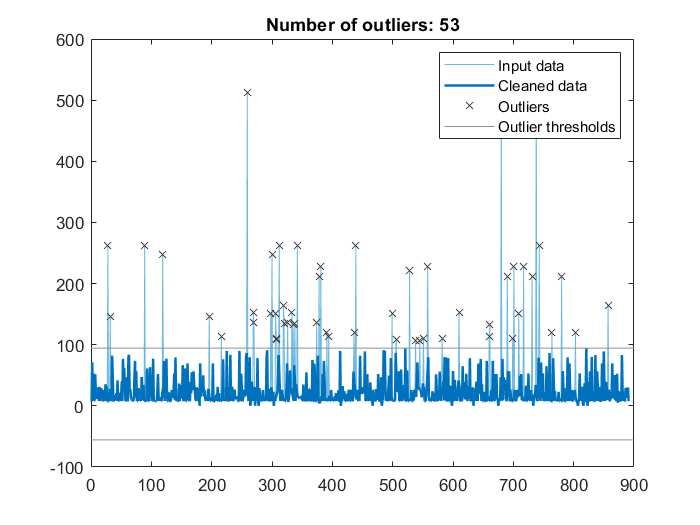

% Remove outliers
[cleanedData2,outlierIndices] = rmoutliers(titanic.Fare,'quartiles',...
    'ThresholdFactor',2.75);

% Visualize results
clf
plot(titanic.Fare,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(find(~outlierIndices),cleanedData2,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(find(outlierIndices),titanic.Fare(outlierIndices),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Compute thresholds and center
[~,thresholdLow,thresholdHigh] = isoutlier(titanic.Fare,'quartiles',...
    'ThresholdFactor',2.75);

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear thresholdLow thresholdHigh

#### Doing programmatically by writing code

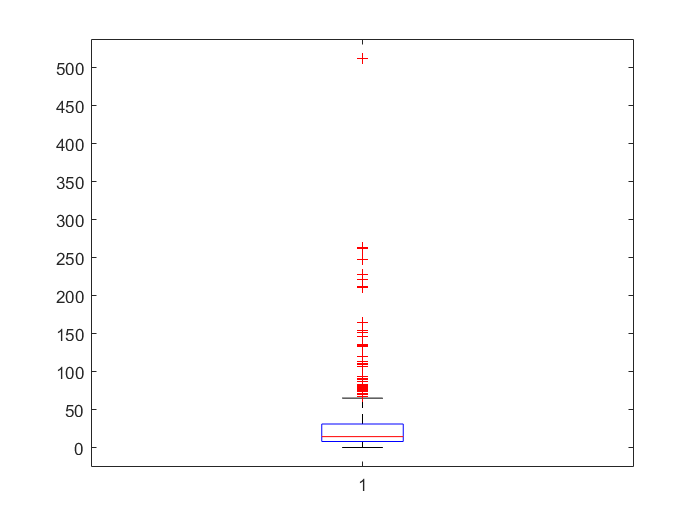

% to check for outliers, one can use boxplot
boxplot(titanic.Fare) % we do not have any!!!!

% to check the percentile distribution
prctile(titanic.Fare,[0,99.90])

ans =          0  512.3292


To remove the outliers (in case we have any)

new_fare = rmoutliers(titanic.Fare,'percentiles',[0,99]) 

new_fare =     7.2500
   71.2833
    7.9250
   53.1000
    8.0500
    8.4583
   51.8625
   21.0750
   11.1333
   30.0708


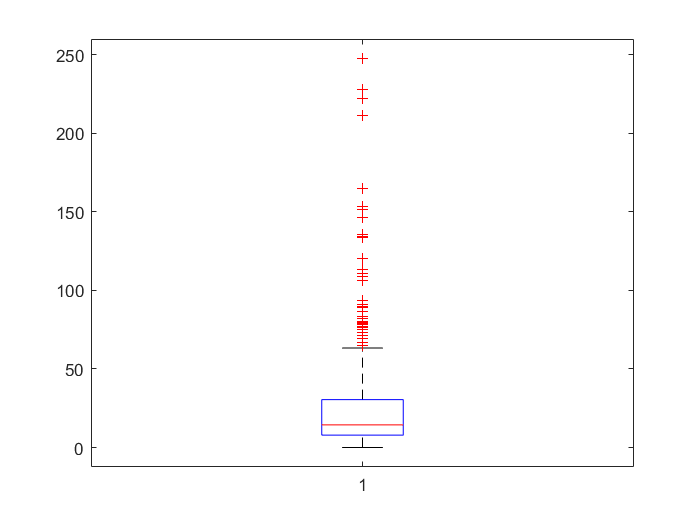

boxplot(new_fare)

Save the pre-processed file

writetable(titanic,'titanic_pre_processed.csv')

# Visualization of Titanic Dataset

Quick plotting can help indicate outliers, skewed data, etc. Lets plot some charts

#### Chart 01: Suvival count by passenger count

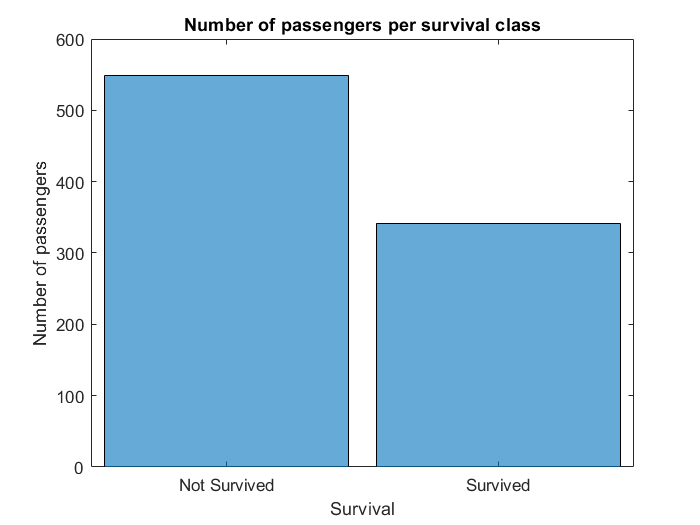

histogram(titanic.Survived)
xlabel("Survival")
ylabel('Number of passengers')
title('Number of passengers per survival class')
xt = xticklabels; 
xt = {'Not Survived', 'Survived'}; % %xt{1} = 'Not Survived', %xt{2} = 'Survived'
xticklabels(xt)

#### Chart 02: Passenger count grouped by Passenger Class

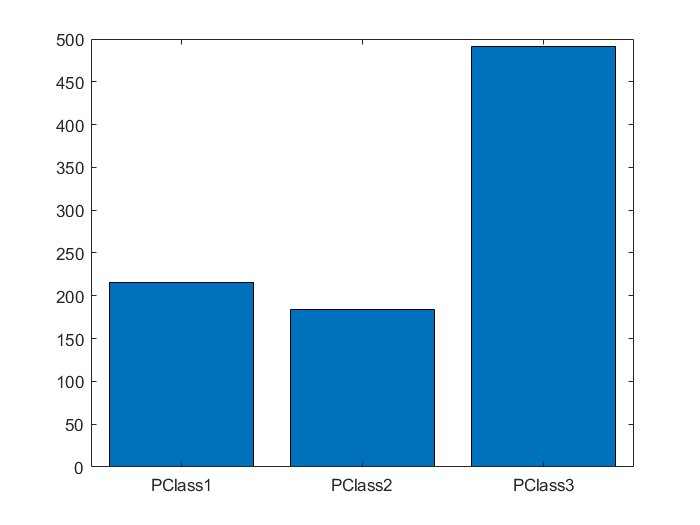

% Number of counts for Passenger class 1
rows = titanic.Pclass == '1';
vals = size(titanic.PassengerId(rows,:));
total_count_pclasss1 = vals(1);
% Number of counts for Passenger class 1
rows = titanic.Pclass == '2';
vals = size(titanic.PassengerId(rows,:));
total_count_pclasss2 = vals(1);
% Number of counts for Passenger class 1
rows = titanic.Pclass == '3';
vals = size(titanic.PassengerId(rows,:));
total_count_pclasss3 = vals(1);

x = categorical(["PClass1" "PClass2" "PClass3"]);
x = reordercats(x,{'PClass1' 'PClass2' 'PClass3'}); % Categoricals can have order associated with them (for the purpose of relational operators).
y = [total_count_pclasss1,total_count_pclasss2,total_count_pclasss3];
bar(x,y);

#### Chart 03: Suvival Count by Passenger class

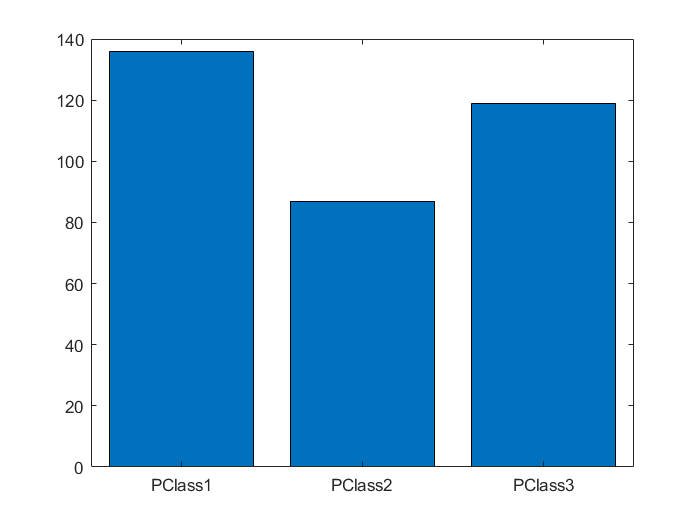

% Number of counts for Passenger class 1
rows = titanic.Pclass == '1';
vals= titanic.Survived(rows,:);
countvals = sum(vals(:) == '1');
total_count_pclasss1 = countvals(1);
% Number of counts for Passenger class 2
rows = titanic.Pclass == '2';
vals= titanic.Survived(rows,:);
countvals = sum(vals(:) == '1');
total_count_pclasss2 = countvals(1);
% Number of counts for Passenger class 3
rows = titanic.Pclass == '3';
vals= titanic.Survived(rows,:);
countvals = sum(vals(:) == '1');
total_count_pclasss3 = countvals(1);
x = categorical(["PClass1" "PClass2" "PClass3"]);
x = reordercats(x,{'PClass1' 'PClass2' 'PClass3'}); 
y = [total_count_pclasss1,total_count_pclasss2,total_count_pclasss3];
bar(x,y);

**Observations**

- More first class passengers survived (about 2/3rd)

- Third class passengers had very little chance of survival (about 7/9 died)

- Second class passengers had a near 50% chance of survival

A better idea would be to plot the survival percentage by class

#### Chart 04: Plotting scatter plot of Age grouped by Survival 

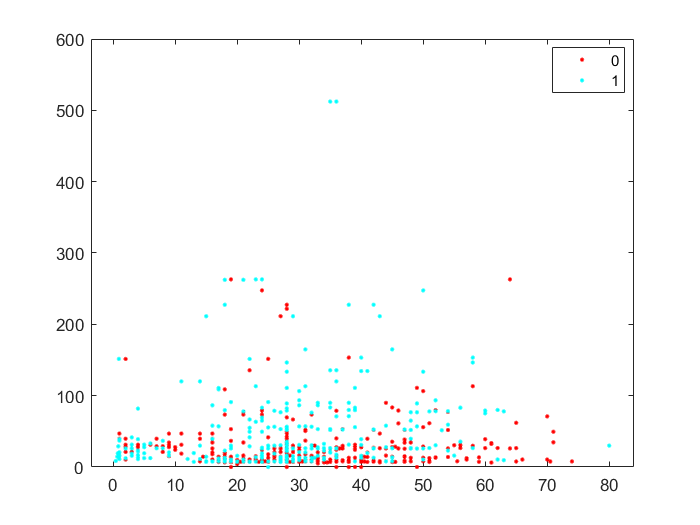

gscatter(titanic.Age,titanic.Fare,titanic.Survived)

#### Chart 05: Plotting scatter plot of Age grouped by Pclass 

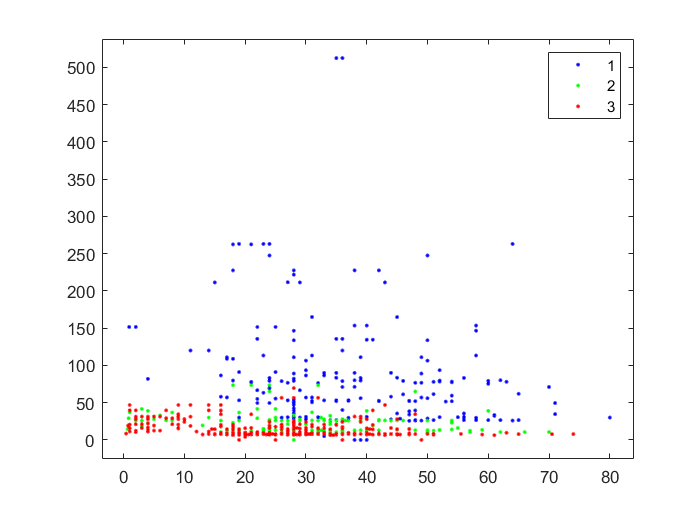

gplotmatrix(titanic.Age,titanic.Fare,titanic.Pclass)

#### Chart 06: Stacked Plot of all column variables

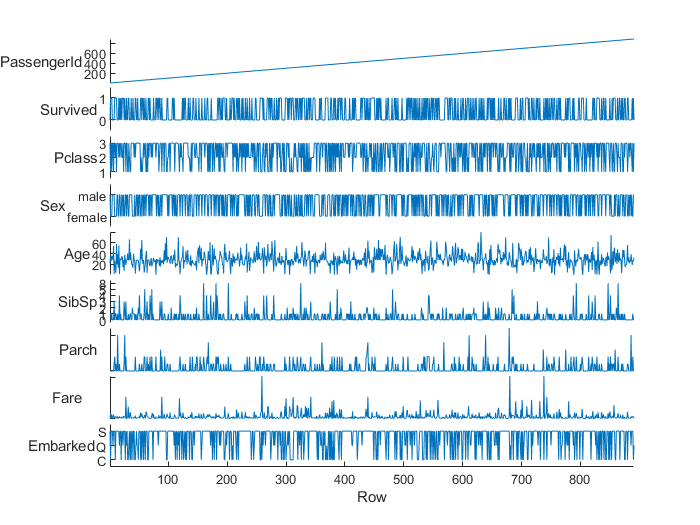

ans =   StackedLineChart with properties:

         SourceTable: [891×11 table]
    DisplayVariables: {'PassengerId'  'Survived'  'Pclass'  'Sex'  'Age'  'SibSp'  'Parch'  'Fare'  'Embarked'}
           XVariable: []
               Color: [0 0.4470 0.7410]
           LineStyle: '-'
           LineWidth: 0.5000
              Marker: 'none'
          MarkerSize: 6

  Show all properties


stackedplot(titanic)

# Machine Learning with Titanic Dataset - Predicting survival on the Titanic 

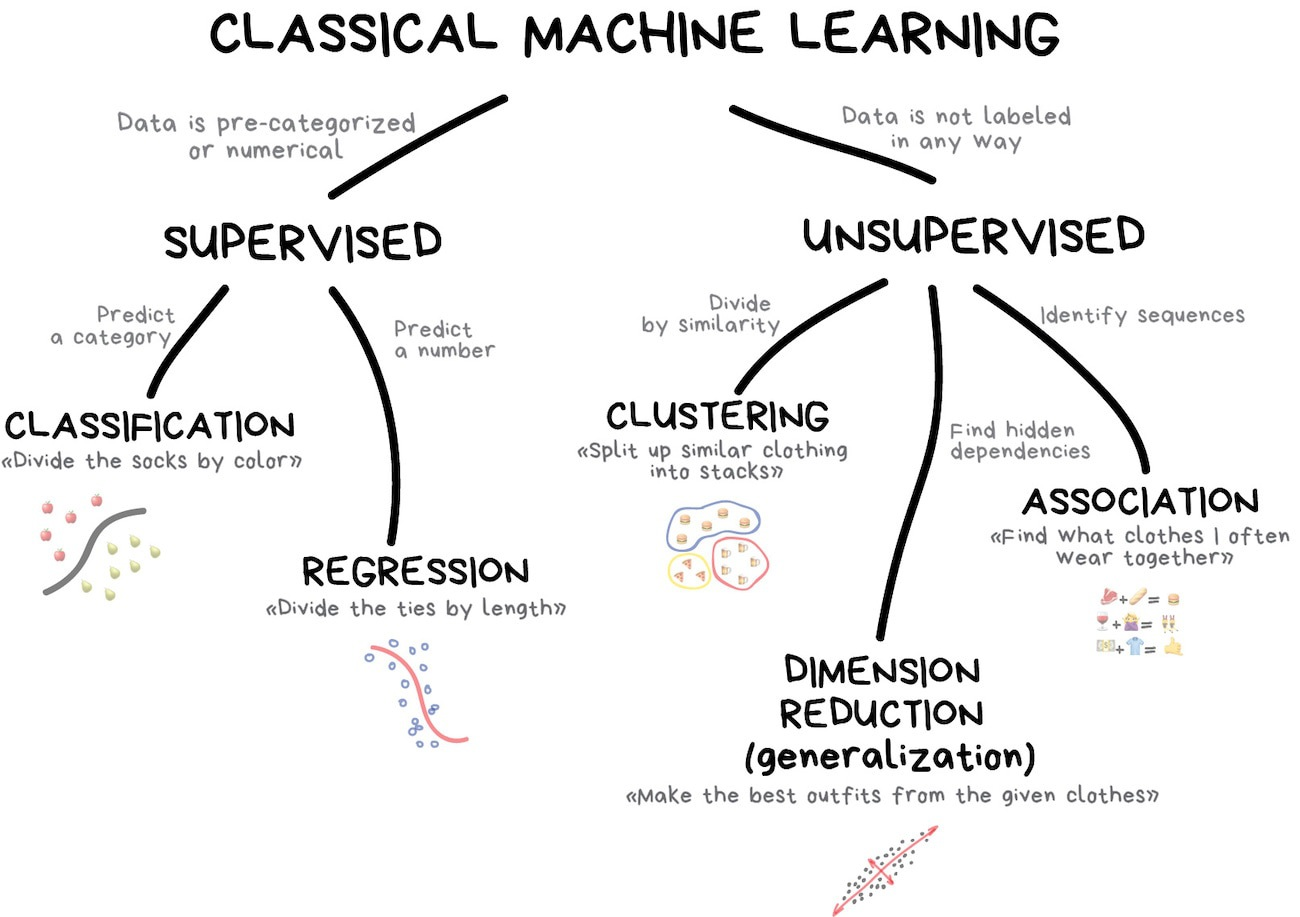

## Classification

In classification problems we split input examples by certain characteristic.

*Usage examples:*

- Spam filters (e.g., Naive Bayes algorithm) 

- Fraud detection (e.g., Decision Trees)

- A search of similar documents

- Sentiment analysis

- Handwritten characters and numbers recognition

Popular algorithms: [Naive Bayes](https://en.wikipedia.org/wiki/Naive_Bayes_classifier), [Decision Tree](https://en.wikipedia.org/wiki/Decision_tree_learning), [Logistic Regression](https://en.wikipedia.org/wiki/Logistic_regression), [K-Nearest Neighbours](https://en.wikipedia.org/wiki/K-nearest_neighbors_algorithm), [Support Vector Machine](https://en.wikipedia.org/wiki/Support_vector_machine)

### Evaluating a classification model

There are multiple ways to evaluate a classification model.

- Construct a ***Confusion Matrix: ***A confusion matrix is a tabular way of visualizing the performance of your prediction model. Each entry in a confusion matrix denotes the number of predictions made by the model where it classified the classes correctly or incorrectly. Target class is the Actual/True class - what really is!!! Output Class is the class predicted by the designed ML algorithm 

- Receiver Operating Curve(ROC) Curve

- Area Under Curve(AUC) metrics.

## Classification Evaluation Criteria

- **Accuracy**: It gives you the overall accuracy of the model, meaning the fraction of the total samples that were correctly classified by the classifier. To calculate accuracy, use the following formula: `(TP+TN)/(TP+TN+FP+FN)`.

- **Precision**: It tells you what fraction of predictions as a positive class were actually positive. To calculate precision, use the following formula: ***TP/(TP+FP)***.

- **Recall**: It tells you what fraction of all positive samples were correctly predicted as positive by the classifier. It is also known as ***True Positive Rate (TPR****)*, *Sensitivity*, *Probability of Detection*. To calculate Recall, use the following formula: ***TP/(TP+FN)***.

- **Sensitivity/Specificity:** It tells you what fraction of all negative samples are correctly predicted as negative by the classifier. It is also known as ***True Negative Rate (TNR)***. To calculate specificity, use the following formula: ***TN/(TN+FP)***.

- **F1-Score: **It combines precision and recall into a single measure. Mathematically it’s the harmonic mean of precision and recall. It can be calculated as follows:

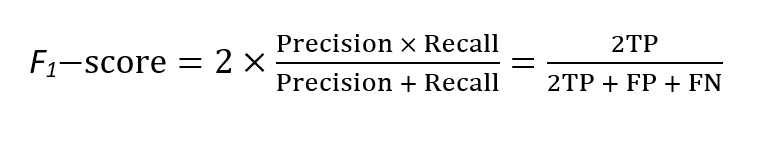

- **ROC/AUC**: A common approach to evaluate a model and the trade-off between *Recall* (*TPR*) and *Fallout*(*FPR*) as functions of the threshold value is to use the Receiver Operating Characteristic(*ROC*) curve and Area Under the Curve(*AUC*). 

#### Confusion Matrix: 

A confusion matrix is a tabular way of visualizing the performance of your prediction model. Each entry in a confusion matrix denotes the number of predictions made by the model where it classified the classes correctly or incorrectly. Target class is the Actual/True class - what really is!!! Output Class is the class predicted by the designed ML algorithm 

- **True Positive (TP):** Number of predictions where the classifier correctly predicts the positive class as positive.

- **True Negative (TN):** Number of predictions where the classifier correctly predicts the negative class as negative.

- **False Positive (FP):** Number of predictions where the classifier incorrectly predicts the negative class as positive.

- **False Negative (FN):** Number of predictions where the classifier incorrectly predicts the positive class as negative.

                                                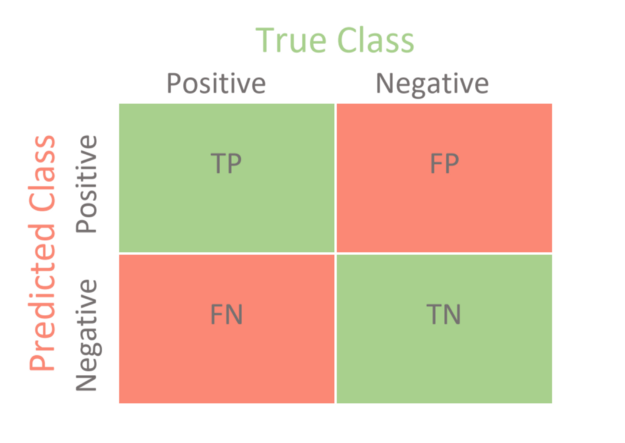

## Supervised Classification Using the Classification App

                    Demo using the Classification App

### Logistic Regression

A logistic regression model is an equation where each predictor is multiplied by a coefficient and summed together.  This sum becomes the argument to the logistic function to predict which of the two classes the observation belongs to. Response values above the specified threshold are in the positive class.  Those below the threshold are assigned to the negative class. **Classification Threshold**:  The threshold for classification can be set between 0 and 1.  The Classification Learner App uses 0.5 as the threshold value.  Use the `fitglm` function to specify a different value.

                      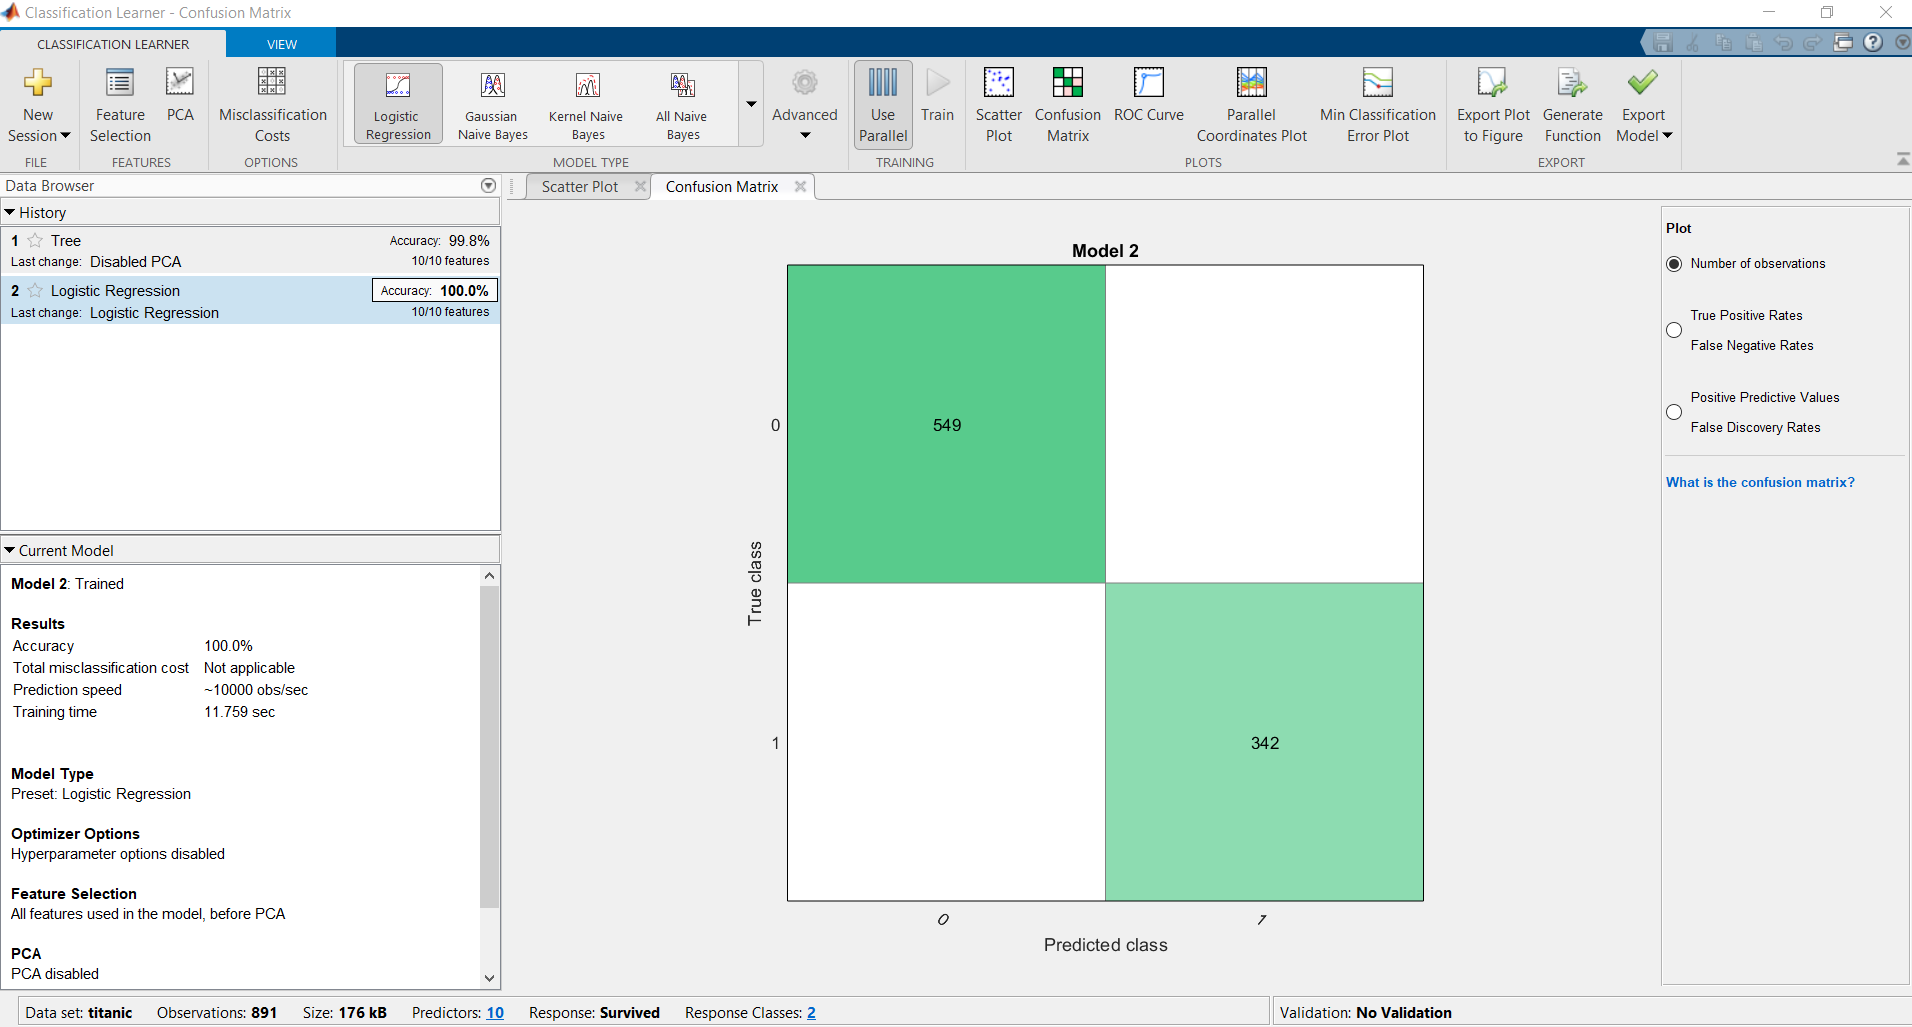

Linear Regression Model (with 10-fold cross validation) 

                      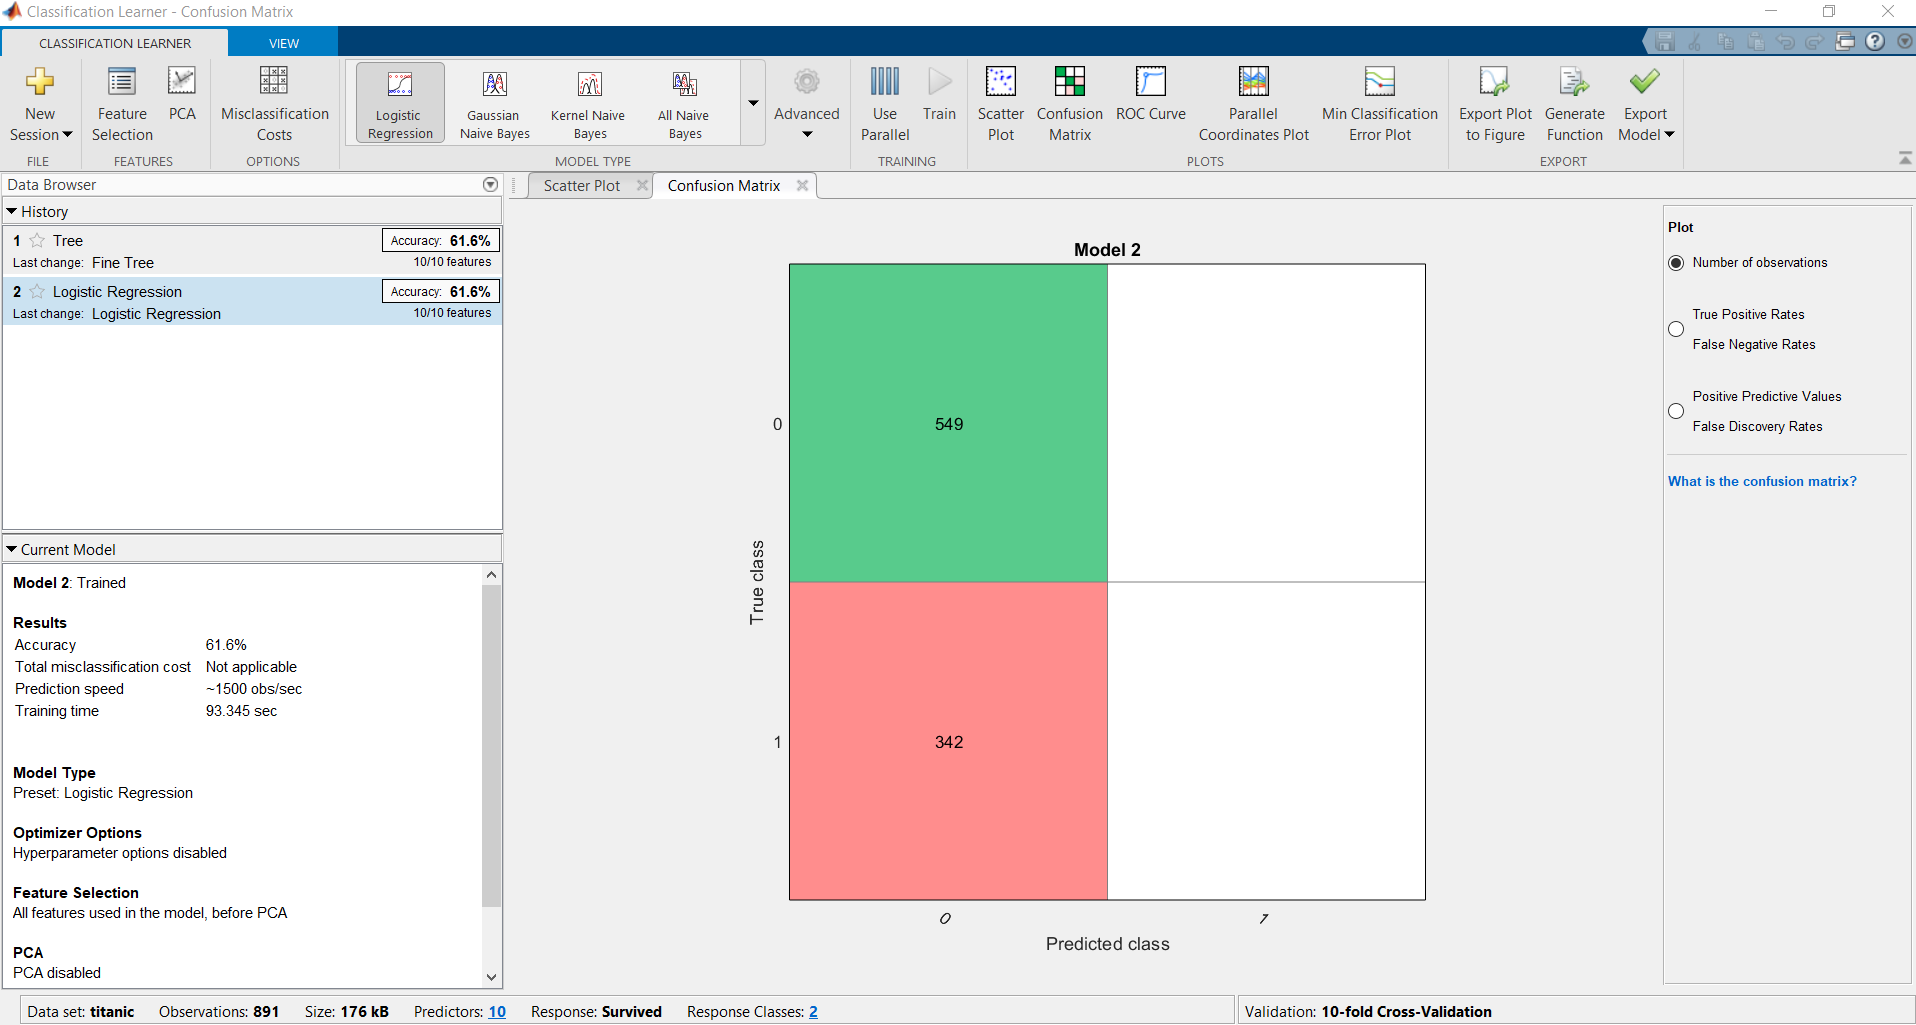

### (Fine) Decision Tree

                     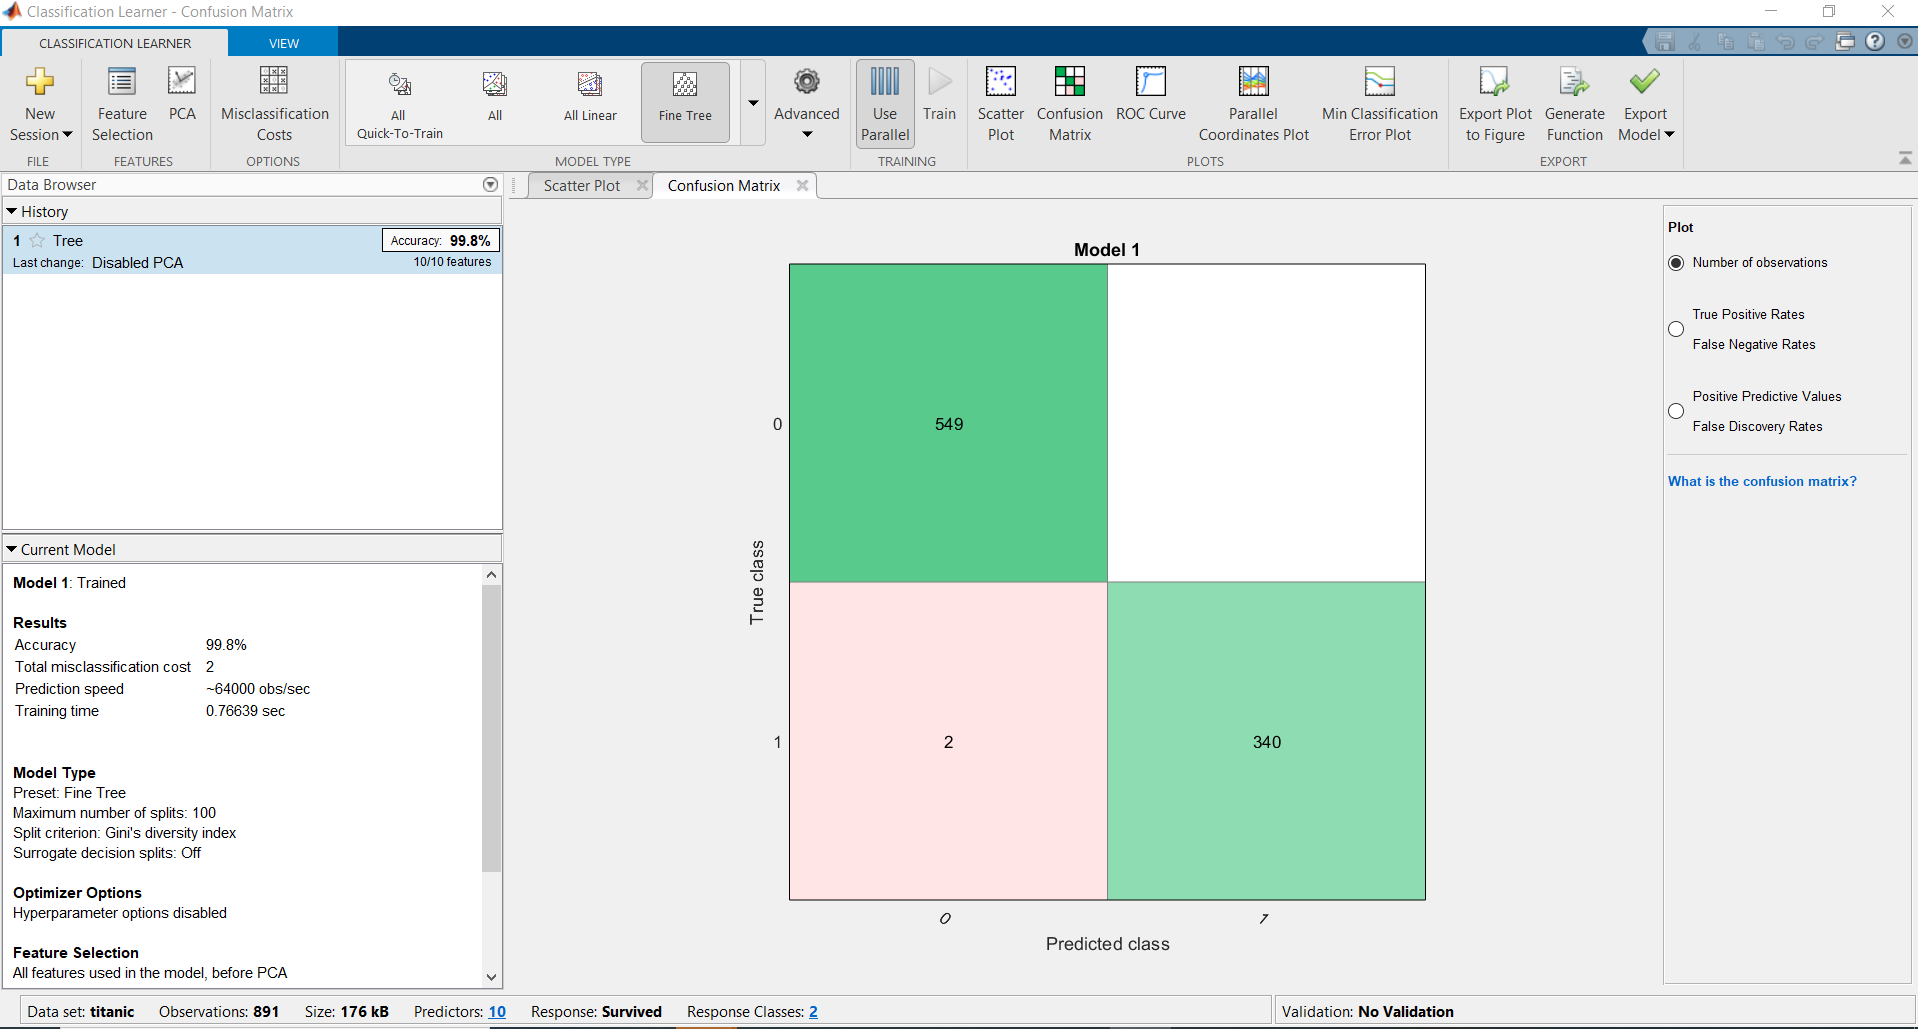

DT with 10-fold CV

                     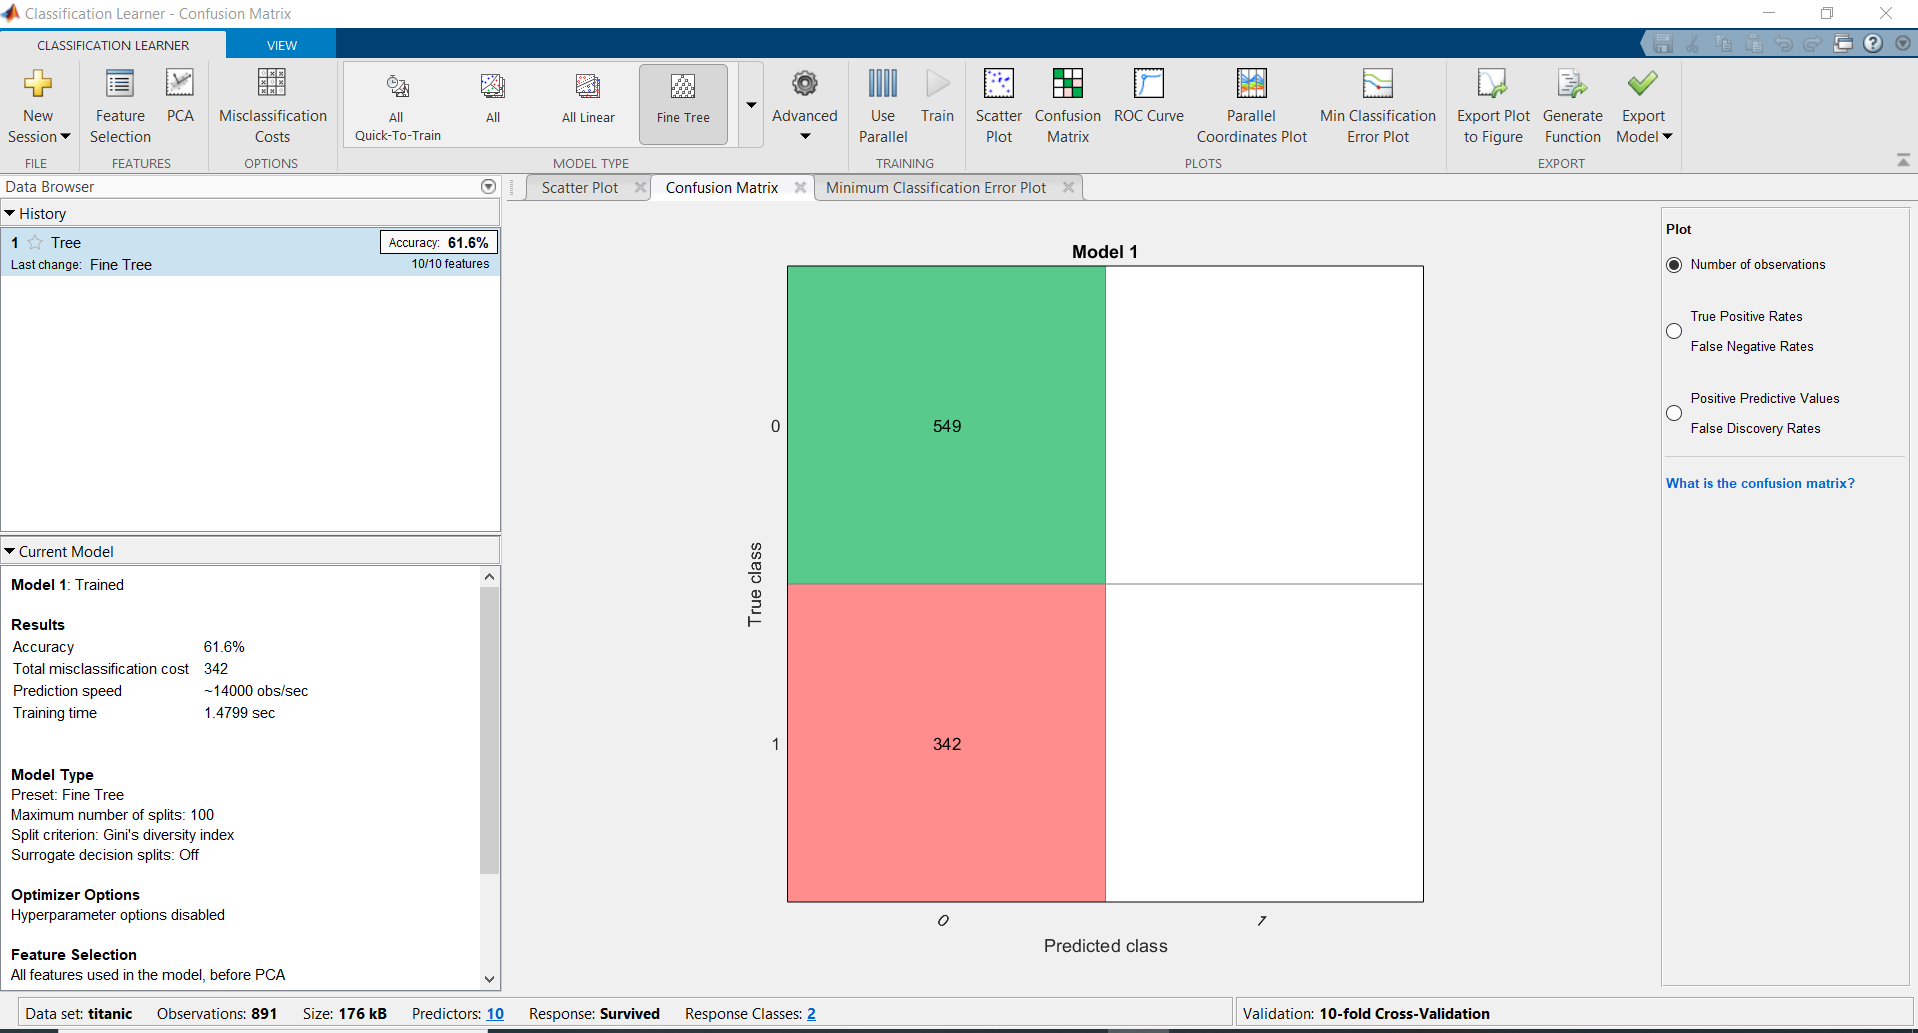

## Solution??

Normalize/Standardize the data!!!!

% % Import the data
% titanic = readtable("C:\Users\Nabajeet Barman\Dropbox\MA6600\Workshop02-25Feb\titanic_pre_processed.csv", opts)
% % To standardize data
% titanic.Age = (titanic.Age - mean(titanic.Age))/std(titanic.Age)
% % To normalize data
% titanic.Age = (titanic.Age - min(titanic.Age)) / (max(titanic.Age) - min(titanic.Age))

### What is the Problem with Categorical Data?

Some algorithms can work with categorical data directly. For example, `a decision tree` can be learned directly from categorical data with no data transform required (this depends on the specific implementation).

Many machine learning algorithms cannot operate on label data directly. They require all input variables and output variables to be numeric. In general, this is mostly a constraint of the efficient implementation of machine learning algorithms rather than hard limitations on the algorithms themselves.

This means that `categorical data must be converted to a numerical form`. If the categorical variable is an output variable, you may also want to convert predictions by the model back into a categorical form in order to present them or use them in some application.

### Integer Encoding

        For example, “*apple*” is 1, “*orange*” is 2, and “*banana*” is 3. The integer values have a natural ordered relationship between each other and machine learning algorithms may be able to understand and harness this relationship.

### One-hot encoding!!!!

For categorical variables where no such ordinal relationship exists, the integer encoding is not enough.

                         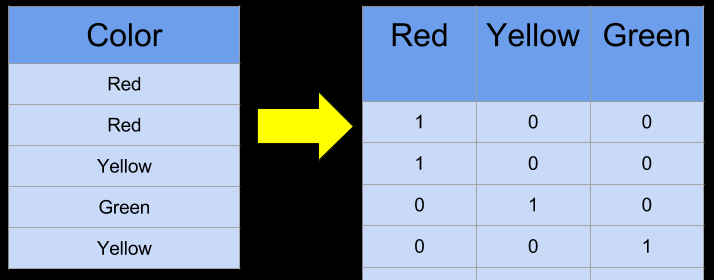

#### When to use a Label Encoding vs. One Hot Encoding?

*We apply One-Hot Encoding when:*

-  The categorical feature is not ordinal (Note: An **Ordinal** Number is a number that tells the position of something in a list, such as 1st, 2nd, 3rd, 4th, 5th etc.)

-  The number of categorical features is less so one-hot encoding can be effectively applied (Note:  if the number of categories are too many, one-hot encoding might not be suitable. In such cases, you should probably limit your algorithms to the ones which can work with either "labelled" categorical data and/or with integer encoding!!!)

*We apply Label Encoding when:*

- The categorical feature is ordinal (like Level 4, Level 5, Level 6 and Level 7 students)

- The number of categories is quite large as one-hot encoding can lead to high memory consumption

% Get unique categories and create indices:
[categories, ~, index] = unique(titanic.Survived)

categories = 2×1 categorical array
     0 
     1 


index =      1
     2
     2
     2
     1
     1
     1
     1
     2
     2


% Create logical matrix:
titanic_survived_one_hot = logical(accumarray([(1:numel(index)).' index], 1))

titanic_survived_one_hot = 891×2 logical array
   1   0
   0   1
   0   1
   0   1
   1   0
   1   0
   1   0
   1   0
   0   1
   0   1


**Unlike binary classification, there are no positive or negative classes here. At first, it might be a little difficult to find TP, TN, FP and FN since there are no positive or negative classes.**

             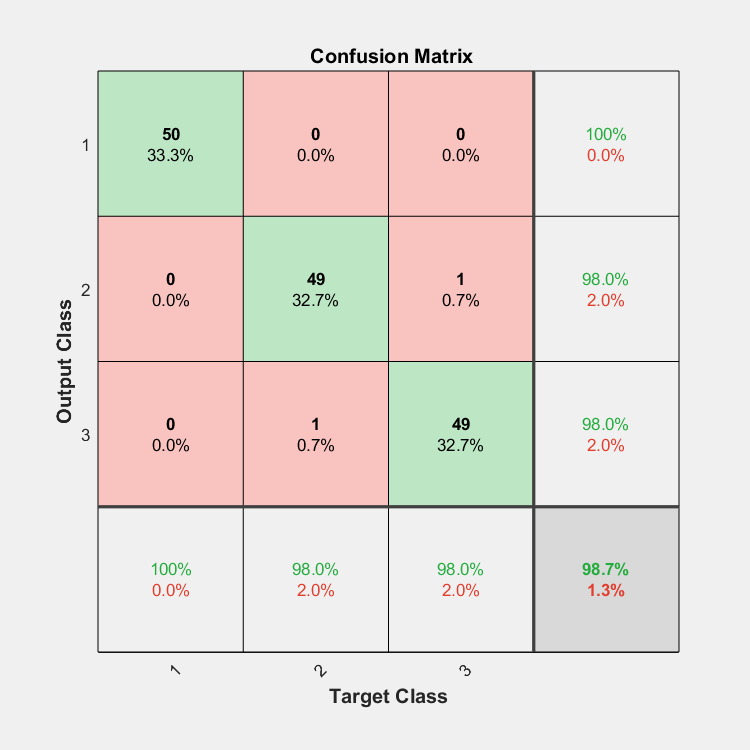

The **rows** correspond to the** predicted class (Output Class)** and the **columns** correspond to the **true class (Target Class)**. The diagonal cells correspond to observations that are correctly classified. The off-diagonal cells correspond to incorrectly classified observations. Both the number of observations and the percentage of the total number of observations are shown in each cell. The column on the far right of the plot shows the percentages of all the examples predicted to belong to each class that are correctly and incorrectly classified. These metrics are often called the precision (or positive predictive value) and false discovery rate, respectively. The row at the bottom of the plot shows the percentages of all the examples belonging to each class that are correctly and incorrectly classified. These metrics are often called the recall (or true positive rate) and false negative rate, respectively. The cell in the bottom right of the plot shows the overall accuracy.

`Important!!! The axis are transposed in the confusion matrix in the Classification Learner App`

             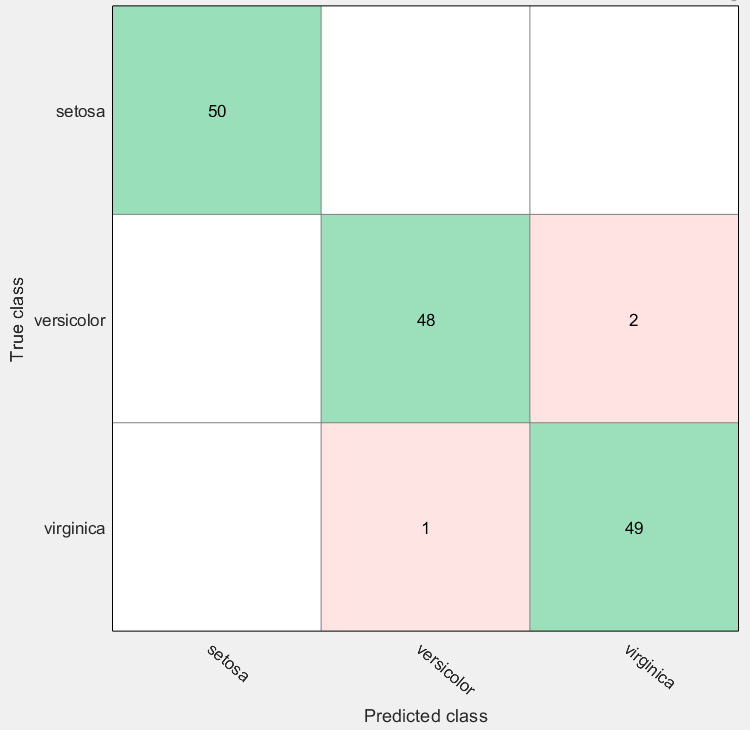

## Supervised Classification Using the Classification Algorithms (by coding)

### Model 01: Logistic Regression

A logistic regression model is an equation where each predictor is multiplied by a coefficient and summed together.  This sum becomes the argument to the logistic function to predict which of the two classes the observation belongs to.

% Fit a Logistic Regression Classifier, predict and find accuracy using the confusion matrix
% we start with moving the predictor column, here Survived towards the end as the algorithm below will assume it to be in the last column!!!
titanic = titanic(:,[1 3:end 2]);
% fitglm(tbl) returns a generalized linear model fit to variables in the table or dataset array tbl. 
% By default, fitglm takes the last variable as the response variable.
log_model = fitglm(titanic,'Distribution','binomial');
ypred = predict(log_model,titanic(:,1:end-1));
ypred = double(round(ypred)); % to round the probabilities to 0 and 1 i.e. 0: not survived, 1: survived
confusion_matrix_LR = confusionmat(titanic.Survived,categorical(ypred));
accuracy_LR = trace(confusion_matrix_LR)/sum(confusion_matrix_LR, 'all')

Recall: Using the app and No Validation  setting, we achieved a similar performance measure (accuracy = 1)

### Model 02: Decision Trees

% fitctree : Fit binary decision tree for multiclass classification
decision_tree = fitctree(titanic(:,1:end-1),titanic(:,end));
% Finding the accuracy of the decision tree model
label = predict(decision_tree,titanic(:,1:end-1));

confusion_matrix_tree = confusionmat(titanic.Survived,label);
accuracy_tree = trace(confusion_matrix_tree)/sum(confusion_matrix_tree, 'all')

Improving the Decision Tree's performance by pruning

When you grow a decision tree, consider its simplicity and predictive power. A deep tree with many leaves is usually highly accurate on the training data. However, the tree is not guaranteed to show a comparable accuracy on an independent test set. A leafy tree tends to overtrain (or overfit), and its test accuracy is often far less than its training (resubstitution) accuracy. In contrast, a shallow tree does not attain high training accuracy. But a shallow tree can be more robust — its training accuracy could be close to that of a representative test set. Also, a shallow tree is easy to interpret. If you do not have enough data for training and test, estimate tree accuracy by cross validation.

**Pruning**

Pruning optimizes tree depth (leafiness) by merging leaves on the same tree branch. [Control Depth or “Leafiness”](https://in.mathworks.com/help/stats/improving-classification-trees-and-regression-trees.html#bsw6baj) describes one method for selecting the optimal depth for a tree. Unlike in that section, you do not need to grow a new tree for every node size. Instead, grow a deep tree, and prune it to the level you choose.

% Improving the Decision Tree's performance by pruning
% We start againg with fitting a decision tree and then viewing it

accuracy_LR = 1

mytree = fitctree(titanic(:,1:end-1),titanic(:,end));

% Finding Best level for pruning using Misclassification error and cross-validation error. Pruning the Tree using the BestLevel
[~,~,~,BestLevel] = cvloss(mytree,'subtrees','all','treesize','min');
prunedtree = prune(mytree,'Level',BestLevel);
%view(prunetree,'mode','graph')

% Finding the accuracy of the pruned decision tree model
label = predict(prunedtree,titanic(:,1:end-1));

accuracy_tree = 0.9978

confusion_matrix_tree_pruned = confusionmat(titanic.Survived,label);
accuracy_tree_pruned = trace(confusion_matrix_tree_pruned)/sum(confusion_matrix_tree_pruned, 'all')

accuracy_tree_pruned = 0.6162

## How to choose the right algorithm?

(Kind of a hack) **The rule of thumb is the more complex the data, the more complex the algorithm.**

For tasks such as these, simple models such as LR, k-NN, etc. should work fine. For more complex data such as image and videos, consider using NN/CNN models.

                     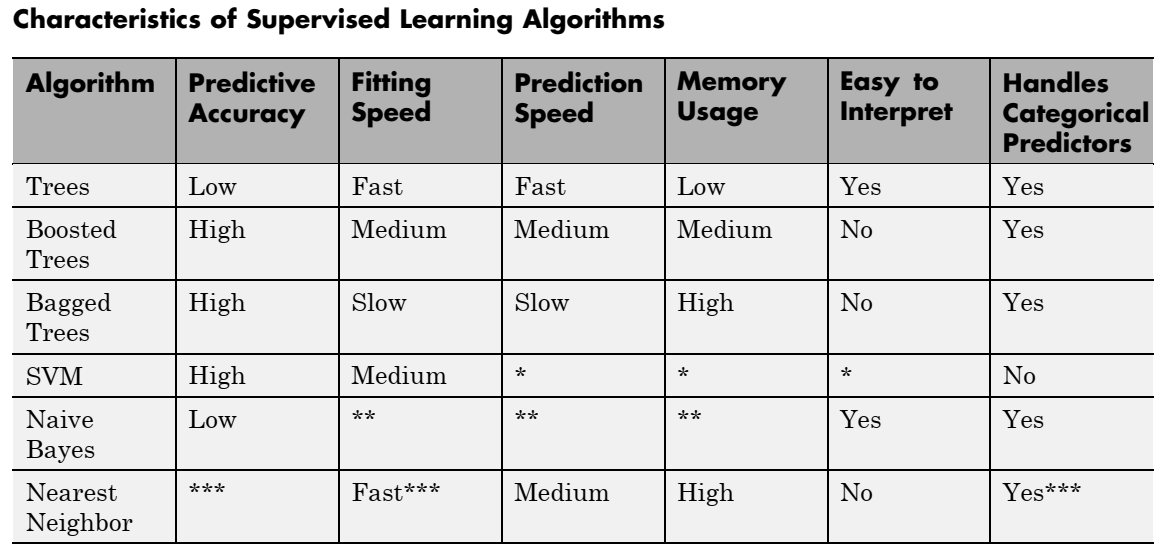

        * — SVM prediction speed and memory usage are good if there are few support vectors, but can be poor if there are many support vectors. When you use a kernel function, it can be difficult to interpret how SVM classifies data, though the default linear scheme is easy to interpret.

        ** — Naive Bayes speed and memory usage are good for simple distributions, but can be poor for kernel distributions and large data sets.

        *** — Nearest Neighbor usually has good predictions in low dimensions, but can have poor predictions in high dimensions. For linear search, Nearest Neighbor does not perform any fitting. For *k*d-trees, Nearest Neighbor does perform fitting. Nearest Neighbor can have either continuous or categorical predictors, but not both.